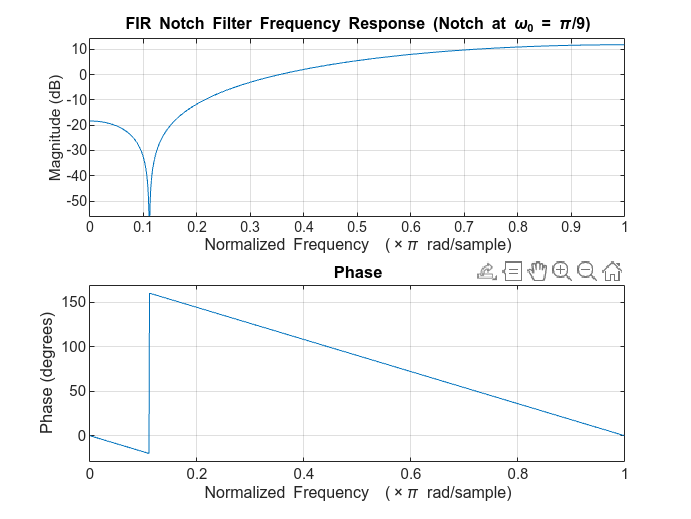

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Part (c): FIR Notch Filter with Linear Phase (Group A=9)
% This code designs and tests a simple 3-tap FIR notch filter that
% removes a sinusoid at frequency omega_0 = pi/9 from the input signal.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% 1) Define the Notch Frequency Based on Group A=9
omega_0 = pi/9;  % If your course defines a different formula, adjust here.

%% 2) Define FIR Coefficients for the Notch Filter
% Transfer function: H(z) = 1 - 2*cos(omega_0)*z^(-1) + z^(-2)
% Coefficients are symmetric => linear phase
b = [1, -2*cos(omega_0), 1];  % Numerator (FIR)
a = 1;                        % Denominator is 1 for an FIR filter

% The difference equation is:
% y(n) = x(n) - 2*cos(omega_0)*x(n-1) + x(n-2)

%% 3) Visualize the Frequency Response
figure('Name','FIR Notch Filter Frequency Response','NumberTitle','off');
freqz(b, a, 1024);
title('FIR Notch Filter Frequency Response (Notch at \omega_0 = \pi/9)');

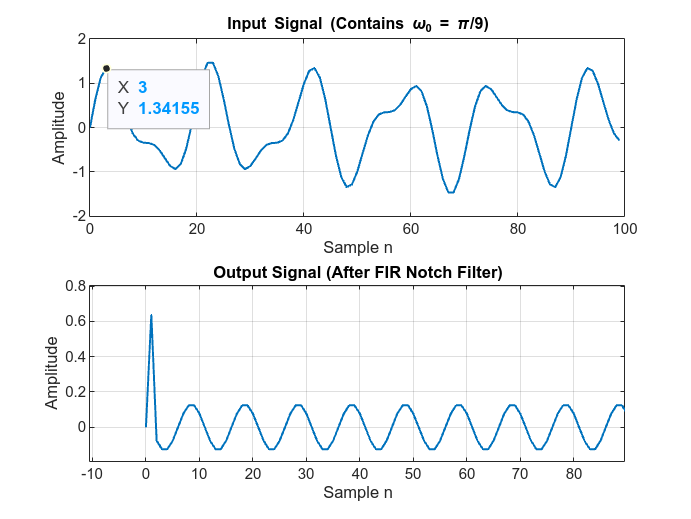


%% 4) Create a Test Input Signal
% We'll combine a sinusoid at the notch frequency + another frequency
n = 0:99;
x = sin(omega_0*n) + 0.5*sin(0.2*pi*n);  % Example mix of two sinusoids

%% 5) Apply the Filter
y = filter(b, a, x);

%% 6) Plot Time-Domain Input vs. Output
figure('Name','Notch Filter: Time-Domain Behavior','NumberTitle','off');

subplot(2,1,1);
plot(n, x, 'LineWidth',1.2);
grid on;
title('Input Signal (Contains \omega_0 = \pi/9)');
xlabel('Sample n'); ylabel('Amplitude');

subplot(2,1,2);
plot(n, y, 'LineWidth',1.2);
grid on;
title('Output Signal (After FIR Notch Filter)');
xlabel('Sample n'); ylabel('Amplitude');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% End of Part (c)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
